# Sinusoid Motion of Chicken Analysis

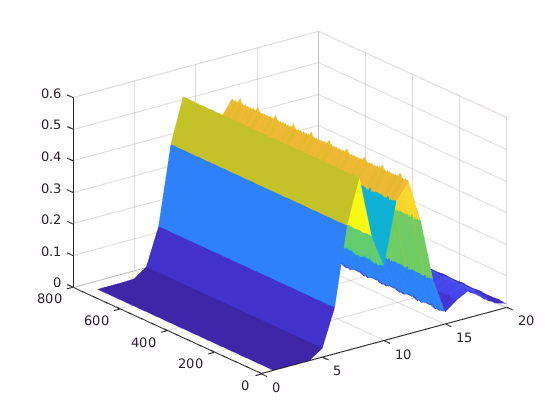

clc
clear
addpath('../functions');
x = linspace(0.0, 9.9, 186);

% Filename
folder = "chicken_water_5";
waveform = "sinusoid";
baseline_n = "baseline-tableonly";
depth = "-1.5cm";
period = "3";
amplitude = "7";
trial = 1;

if (waveform == "sinusoid")
    filename = strcat(folder, "/", waveform, "_D", depth, "_T", ...
        period, "_A", amplitude, "_", num2str(trial), ".mat");
end
if (waveform == "chirp")
    filename = strcat(folder, "/", waveform, "_D", depth, "_A", amplitude, "_", num2str(trial), ".mat");
end
if (waveform == "patient")
    filename = strcat(folder, "/", waveform, "_D", depth, ".mat");
end

%VariableName
dataType = "bb";
dacMIN = "0";
dacMAX = "1400";
frequency = "3";
varName = char(strcat(dataType, dacMIN, "_", dacMAX, "f", frequency));

load(filename, varName);
s_rx = bb0_1400f3;
surf(abs(s_rx(:,1:20)), 'linestyle', 'none');

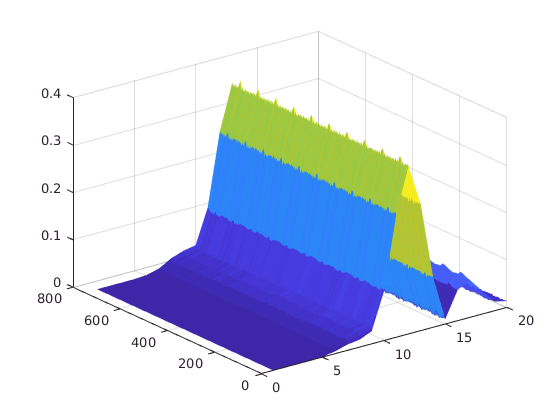


% Subtract baseline
for i = 1:3
   baseline(i) = load(strcat(folder, "/", baseline_n, "_", num2str(i)), varName);
end
baseline_avg = 1/3*(baseline(1).(varName) + baseline(2).(varName) + baseline(3).(varName));

for i = 1:length(s_rx)
    s_rx(i,:) = s_rx(i,:) - baseline_avg;
end

surf(abs(s_rx(:,1:20)), 'linestyle', 'none');


clear amplitude dacMAX dacMIN dataType depth frequency material period trial waveform


## Creating an Input Signal

Fs = 23.328e9; % Sampling Frequnecy
Bw = 1.5e9;    % Bandwidth
Fc = 8.748e9;  % Center Frequency

[s_tx, S_tx, t, f] = uwb_wavelet(Fs, Bw, Fc);

clear beta fftPulse L P1 P2 pulse tao tc n


## Use the Match and Downconvert method

% Get the RF values
load(filename, 'rf0_1400f3');
s_rx = rf0_1400f3;

% RF Baseline
for i = 1:3
   baseline_rf(i) = load(strcat(folder, "/", baseline_n, "_", num2str(i)), 'rf0_1400f3');
end
baseline_rf_avg = 1/3*(baseline_rf(1).('rf0_1400f3') + baseline_rf(2).('rf0_1400f3') + baseline_rf(3).('rf0_1400f3'));

% Baseline No Chicken
for i = 1:3
   baseline_rf_nc(i) = load(strcat(folder, "/", "baseline_nochicken", "_", num2str(i)), 'rf0_1400f3');
end
baseline_rf_nc_avg = 1/3*(baseline_rf_nc(1).('rf0_1400f3') + baseline_rf_nc(2).('rf0_1400f3') + baseline_rf(3).('rf0_1400f3'));


% Match and downconvert
chicken_matched_baseline = matched(baseline_rf_avg, s_tx, Fc);
chicken_matched_baseline_nc = matched(baseline_rf_avg, s_tx, Fc);

[s_rx_l, ~] = size(s_rx)

s_rx_l = 750

for i = 1:s_rx_l
    chicken_matched(i,:) = matched(s_rx(i,:), s_tx, Fc);
    chicken_matched_net(i,:) = chicken_matched(i,:) - chicken_matched_baseline;
end 


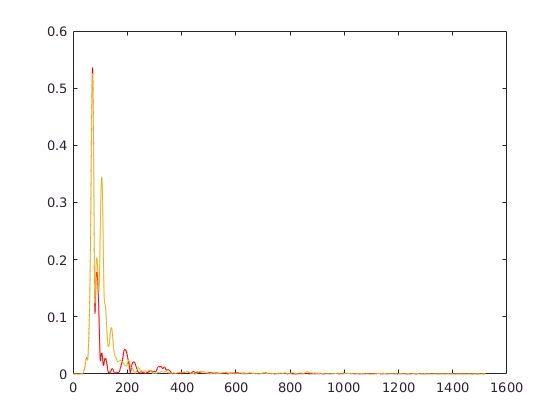

plot(abs(chicken_matched_baseline), 'Color', 'black');
hold on;
plot(abs(chicken_matched_baseline), 'Color', 'red');
hold on;
plot(abs(chicken_matched(1,:)));
hold off;

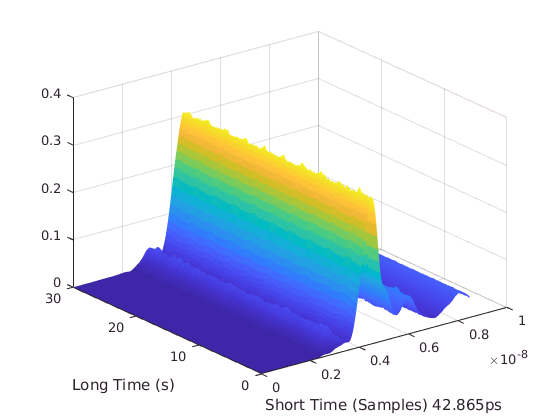

% Calibrate with the baseline

t_long = 0:1/25:30-1/25;
t_sample = 0:1/Fs:1/Fs*199;

chicken_matched_data = chicken_matched_net(:,1:200);
surf(t_sample, t_long, abs(chicken_matched_data), 'linestyle', 'none');
xlabel('Short Time (Samples) 42.865ps')
ylabel('Long Time (s)')

## Use Motion detection

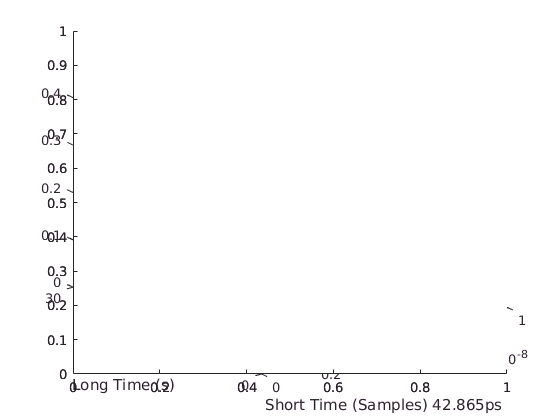

%S_tx_m = motion_detect(s_rx, 5);

Rxy = chicken_matched_data;
window = 5;

[Rxy_l, Rxy_w] = size(Rxy);
windows = 1:Rxy_l-window;

S_tx_m = zeros(Rxy_l-window, Rxy_w);
for i = windows
    S_tx_m(i,:) = var(Rxy(i:i+window, :));
end 

h1 = axes;

surf(t_sample, t_long(1:end-window), S_tx_m(:, 1:200), 'LineStyle', 'None');

Error using surf (line 82)
Data dimensions must agree.


title('Locations of high positional variance of moving chicken profile');
xlabel('Short Time (Samples) 42.865ps')
ylabel('Long Time (s)')
set(h1, 'Ydir', 'reverse')
set(h1, 'Xdir', 'reverse')
set(h1, 'YAxisLocation', 'Left')

radaroffset = 2.3e-10;
rindex_water = sqrt(90);
rindex_heart = sqrt(46);
time_to_surface = 2*(0.198/3e8) + radaroffset
time_to_chicken_min = 2*(0.198/3e8 + 0.008/3e8*rindex_water)
time_to_chicken_cen = 2*(0.198/3e8 + 0.015/3e8*rindex_water)
time_to_chicken_max = 2*(0.198/3e8 + 0.022/3e8*rindex_water)

time_to_chicken2_min = 2*(0.198/3e8 + 0.008/3e8*rindex_water + 0.027/3e8*rindex_heart)
time_to_chicken2_cen = 2*(0.198/3e8 + 0.015/3e8*rindex_water + 0.027/3e8*rindex_heart)
time_to_chicken2_max = 2*(0.198/3e8 + 0.022/3e8*rindex_water + 0.027/3e8*rindex_heart)
